**Exercici 2. **

Aquest exercici està basat en una simplificació de la contribució Astrophotography with MATLAB: Imaging the Orion Nebula per Loren Shure,6 de Novembre 2020.

La idea de l’exercici es basa en fusionar dues imatges de la nebulosa d’Orion en una única imatge per aconseguir millor contrast i reducció del soroll (fig.1). 

 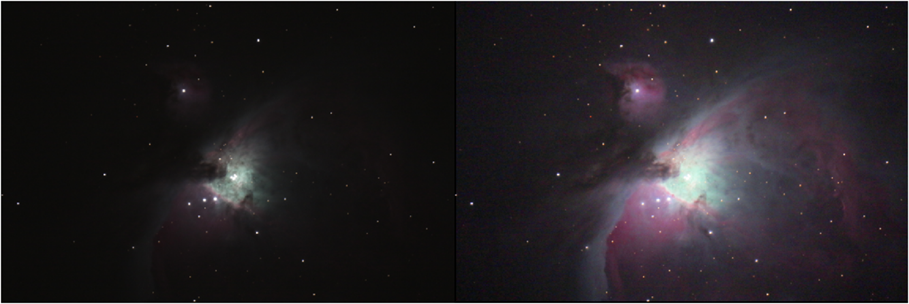

                              a)                                                               b)

                 Fig. 1 Nebulosa d’Orion: a) Imatge original, b) Imatge resultant

**        1.  El primer que farem és llegir les imatges i les convertim a *****double*****.**

      A = double(imread('_MG_7735.JPG'))/255;
      B = double(imread('_MG_7737.JPG')) /255;

       ** 2.  Comprovem que passaria si superposem les imatges directament. Per veure-ho, restem les imatges píxel a píxel i el resultat el re-escalem entre 0-1. **

DIF = abs(A-B); % imatge diferencia
maxim = max(DIF(:));
DIF = DIF/maxim; % dividim pel seu valor màxim
%imshow(DIF); Per tal de reduïr la mida del fitxer no puc mostrar la imatge

S’observa en la imatge diferència que les imatges apareixen mogudes una respecte a l’altre. Això és degut a la rotació terrestre i a que les imatges han estat preses en instants de temps diferents.  Entre una imatge i l’altre han transcorregut alguns minuts i en conseqüència les imatges apareixen desplaçades aproximadament 20 píxels en horitzontal i 20 píxels en vertical.

   **    3.  Traslladem per codi  la imatge B 20 píxels en diagonal i observem que les imatges s’ajusten prou bé. **

       Nota: Aquest desplaçament d’una imatge sobre l’altre es pot fer automàticament i en temes posteriors es veurà com fer-ho. 

       Penseu que utilitzant centenars d’imatges obtindríem una imatge molt millorada pel que fa a l’exposició (captació de llum).

Bd = imtranslate(B,[20, -20]);
DIF = abs(A-Bd);
maxim = max(DIF(:));
DIF = DIF/maxim;
%imshow(DIF); Per tal de reduïr la mida del fitxer no puc mostrar la imatge

**      4.  Ara ja podem sumar les dues imatge A i Bd per obtenir una nova imatge “millorada”.**

**a) Equalització (adapthisteq)**

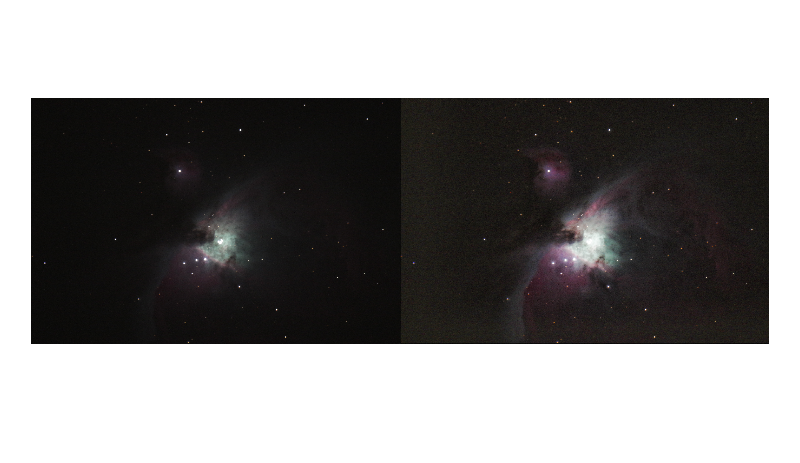

Am = (A+Bd)/2; % imatge millorada
[H,S,L] = convertToHSL(Am);
L2 = adapthisteq(rgb2gray(Am)); 
Am2 = convertFromHSL(H,S*1.5,L2);
montage ({A,Am2});

Equalitzant l'histograma de la component L de la imatge amb adapthisteq() i incrementant la saturació de la imatge obtenim un resultat prou bo. Encara i això la imatge te força soroll i els colors no son prou vius.

**b) Métode trobat al link de la pràctica**

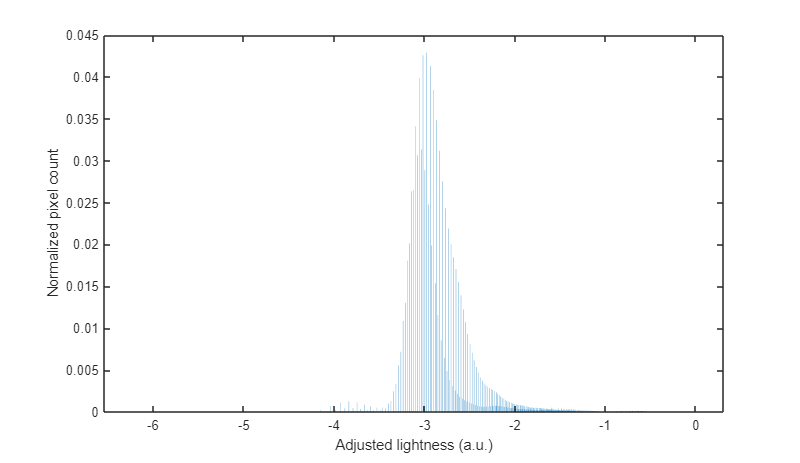

Am = (A+Bd)/2; % imatge millorada
[H,S,L] = convertToHSL(Am);
L2 = log(L);
histogram(L2,'Normalization','probability','EdgeColor','none');
xlabel('Adjusted lightness (a.u.)')
ylabel('Normalized pixel count')

Observem en un histograma el log de la component L (lightness) de la imatge. Com els valors de L originals és troben entre 0 i 1, en fer l'operació log ens queden valors negatius. El pic que observem és la regió fosca de la imatge.

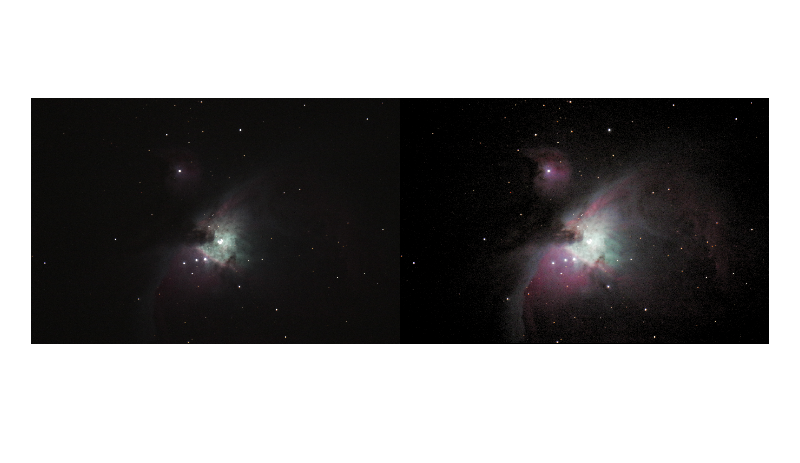

blacklevel = -3;
L2 = rescale(L2,"InputMin",blacklevel);
Am2 = convertFromHSL(H,S*1.5,L2);
montage ({A,Am2});

Ajustem la part en nivell d'il·luminació de la part fosca de la imatge i ho tornem a passar a un interval [0,1]. Tornem a construir la imatge amb el nou nivell d'il·luminació L2. Podem veure que a la imatge resultant les zones fosques es veuen millor i els colors són més vius, tot i això podem veure que hi ha una mica de soroll.

**c) Fent servir la funció imlocalbrighten**

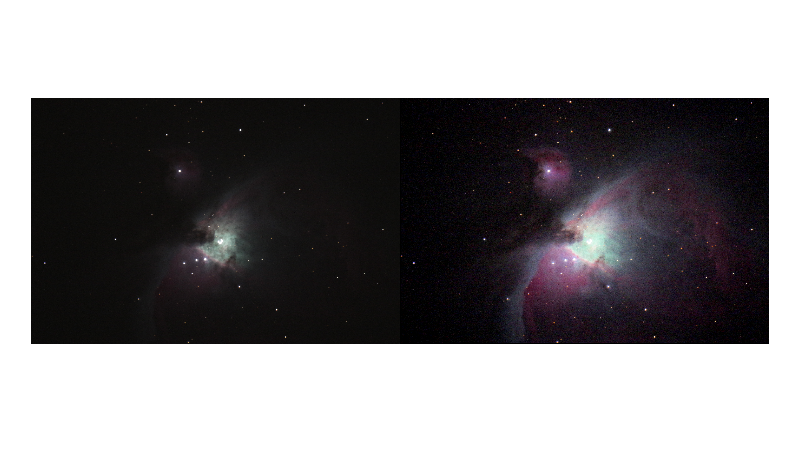

Am = (A+Bd)/2; % imatge millorada
Am = imlocalbrighten(Am,0.8); % 
Am = imadjust(Am,[0.14 0.14 0.14; 1 1 1], []);
montage ({A,Am});

La funció imlocalbrighten() il·lumina les zones més fosques de la imatge original i la funció imadjust() ens permet retocar la saturació de la imatge. La imatge resultant és molt similar a l'obtinguda amb el mètode anterior, l'única diferència és la saturació dels colors, que en aquesta última els colors son més vius.

**Conclusió:**

Tant el mètode trobat a l'enllaç de la pràctica com fer servir funcions del toolbox de image processing de MatLab donen un molt bon resultat a l'hora d'augmentar el contrast a les zones fosques sense sobre-il·luminar les zones clares, el mètode d'equalització de l'histograma del component L es bo pero no és ni tan parametrizable ni ens dona un resultat tant bo com els altres dos. Aquest últim mètode (funcions del toolbox) és més còmode de fer servir i més fàcilment ajustable i dóna un resultat lleugerament més nítid.

function [H,SL,L] = convertToHSL(RGB)
%convertToHSL Converts image from RGB to HSL colorspace
% https://en.wikipedia.org/wiki/HSL_and_HSV

HSV = rgb2hsv(RGB);

% Convert from HSV to HSL
% HL = HV = H;
H = HSV(:,:,1);
SV = HSV(:,:,2);
V = HSV(:,:,3);

L = V-(0.5.*V.*SV);

SL = (V-L) ./ min(L, 1-L);
SL(L==0 | L==1) = 0;
end

function RGB = convertFromHSL(H,SL,L)
% convertFromHSL Converts image from HSL to RGB colorspace
% https://en.wikipedia.org/wiki/HSL_and_HSV

% Convert from HSL to HSV
% HV = HL = H;
V = L+SL.*min(L, 1-L);
SV = 2*(1-L./V);
SV(V==0) = 0;

HSV = cat(3,H,SV,V);

RGB = hsv2rgb(HSV);

end